My Convolution for causal signals only

x=ones(1,4);

x2 =      4     0     0     0


x2 =      4     3     0     0


x2 =      4     3     2     0


x2 =      4     3     2     1


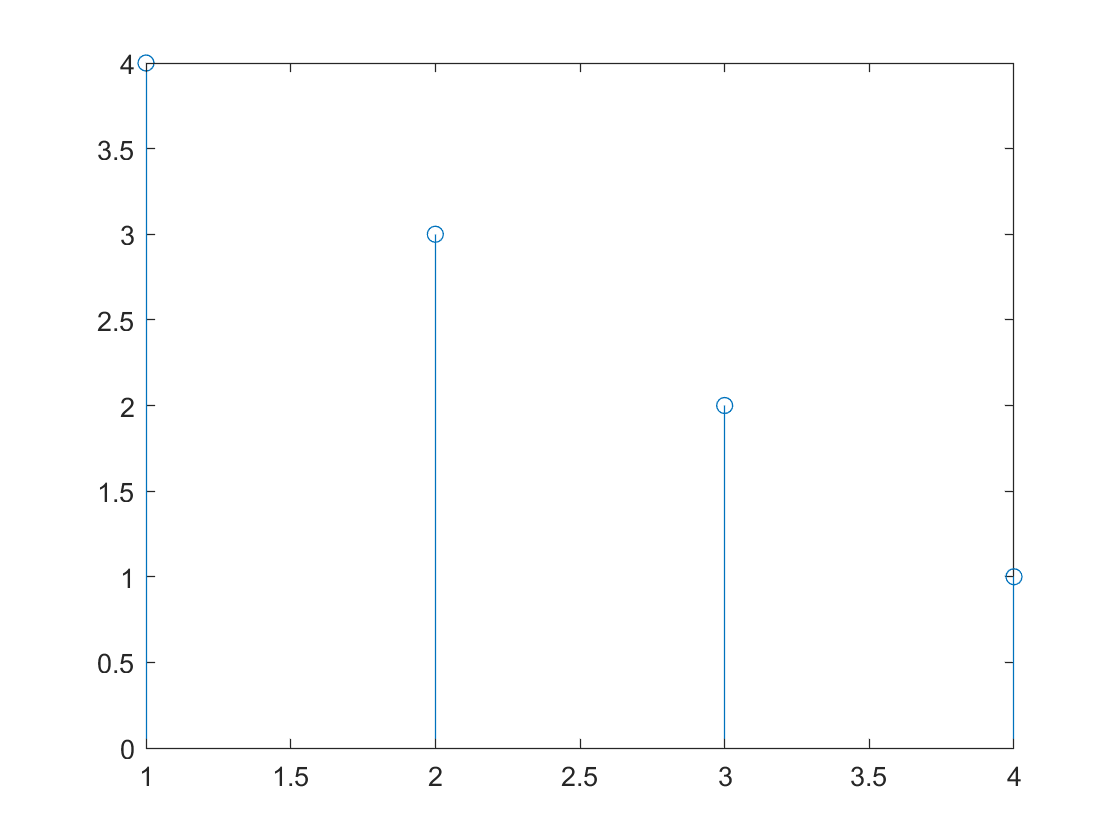

x2=zeros(1,4);


for n=1:length(x)
    x2(n)=sum(x(n:length(x)))
end

stem(x2)

So is filtering just soemsort of convolution?

if false
    N=2^18;
    n=[0:1:N-1];
    s1=sin(2*pi*1*n/N);
    s2=sin(2*pi*10^2*n/N);
    s3=sin(2*pi*10^3*n/N);
    s4=sin(2*pi*10^4*n/N);
    s5=sin(2*pi*2*10^4*n/N);
    s6=sin(2*pi*3*10^4*n/N);
    s7=sin(2*pi*4*10^4*n/N);
    s8=sin(2*pi*5*10^4*n/N);
    
    s_ges=s1+s2+s3+s4+s5+s6+s7+s8;
    figure;plot(fftshift(abs(fft(s_ges))))
else 
    N=2^4;
    n=[0:1:N-1];
    s1=sin(2*pi*1*n/N);
    s2=sin(2*pi*6*n/N);
    s3=sin(2*pi*7*n/N);
    s_ges=s1+s2+s3;
    figure('Name','Freq-Spectrum s_ges')
    subplot(2,1,1)
    stem(fftshift(abs(fft(s_ges))))
    grid on;
    subplot(2,1,2)
    plot(s_ges)
    grid on;
end

Ok we have a signal, let's make a filter! jei lets eliminate the first two frequencies, how do we do that? Something with fomrula 6.5 dunno....

if false
    
elseif true
    b_1=[1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
    
    figure('Name', 'Freq. Resp. of b_1(n)')
    subplot(2,1,1)
    freqz(b_1);
    subplot(2,1,2)
    zplane(b_1);
    
    figure;
    subplot(2,2,1)
    plot(conv(s_ges,b_1))
    subplot(2,2,2)
    plot(s_ges)
    subplot(2,2,3)
    stem(fftshift(abs(fft(conv(s_ges,b_1)))));
    subplot(2,2,4)
    stem(fftshift(abs(fft((s_ges)))))
    
elseif false
    b_2=[1 0.1 0 0 0 0 0 0 0 0 0 0 0 0 0]
    
    figure('Name', 'Freq. Resp. of b_2(n)')
    subplot(2,1,1)
    freqz(b_2);
    subplot(2,1,2)
    zplane(b_2);
    
    subplot(2,2,1)
    plot(conv(s_ges,b_2))
    subplot(2,2,2)
    plot(s_ges)
    subplot(2,2,3)
    stem(fftshift(abs(fft(conv(s_ges,b_2)))));
    subplot(2,2,4)
    stem(fftshift(fft(abs(s_ges))));
end
